Inicializácia

n0 = 1;%index prveho suboru
n = 6;%pocet suborov
m = 19;%predpoklad pocet derivacii vstupu (zmeny vstupu)
w = 300;%Pocet dat povaz ako ustalene
endOfData = 13542;
dataStore = zeros((m)*w,n+2);
dataPlot = zeros(endOfData,6);
dataPlotTime = zeros(endOfData,6);

Identifikovane polynomy

pGain = [-7.74558355399971e-09 7.92523655765039e-06 -0.00291980737503381 0.463728547328537 -23.1386227555553];
pT = [1.10661505286941e-07 -5.48243874702451e-05 0.00740611980939077 -0.00882197108389277];
p = [1.27264127791514e-06,-0.000693202019254355,0.101241610731183,5.53942212609170,-881.974593934446];

Nacitanie csv dát

for i=1:n
    fileName = ['D:/gitHub/TP/TP-PlainData/allSig_log_prev_mer',num2str((n0-1)+i),'_up.csv'];
    dt = csvread(fileName);
    dataSubPlot = zeros(length(dt),n+1);
    dataPlot(1:endOfData,i) = dt(1:endOfData,3);
    dataPlotTime(1:endOfData,i) = dt(1:endOfData,1);
    diffVal = diff(dt(2:end,2));
    ids = find(or(diffVal > 0,diffVal < 0));
    ln = size(ids,1);
    if ln == m
       ln = size(dt,1);
       id = [ids;ln];
       idSim = ids;   
       dataSubPlot(1:length(dt),i) =  dt(1:length(dt),3);  
       for j=1:m
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = dt(idSim(j):idSim(j)+w-1,1);
                dataStore(1+w*(j-1):w*j,2) = dt(idSim(j):idSim(j)+w-1,2);
            end
            dataStore(1+w*(j-1):w*j,i+2) = dt(idSim(j):idSim(j)+w-1,3);
       end
    end
end

SIMULINK

sim_u = dataStore(:,1:2);
out = sim("model.slx");
dataSubPlot(1:length(dt),7) =  dt(1:length(dt),1); 

Určenie dynamiky pracovného bodu

p0 = 206;%Pracovny bod pred Jed. skok
pBod = 214;%Pracovny bod po Jed. skoku

pIds = find(dataStore(:,2)==pBod);
pData = dataStore(pIds,:);

pDataMean = zeros(w,3);
pDataMean(:,1:2) = pData(:,1:2);
pomDt = pData(:,3:end)';
pDataMean(:,3) = mean(pomDt);

Normalizovanie

pDataMean(:,1) = pDataMean(:,1) - pDataMean(1,1);
pDataMean(:,2) = pDataMean(:,2) - p0;
pDataMean(:,3) = pDataMean(:,3) - pDataMean(1,3);

Identifikácia

t = pDataMean(1:end-2,1);
u = pDataMean(1:end-2,2);
y = pDataMean(1:end-2,3);

Sústava 1. rádu

y1_v = 0.33*y(end);
t1_v = 0.33*t(end);
y2_v = 0.70*y(end);
t2_v = 0.70*t(end);
yMean = mean(y(end-100:end));

K = yMean/u(1);
plotK = yMean;

[r,c] = find(y>=y1_v,1,"first");
y1 = y(r,c);
t1 = t(r,c);

[r,c] = find(y>=y2_v,1,"first");
y2 = y(r,c);
t2 = t(r,c);
s = tf("s");
T = 1.245*(t2-t1);
D = 1.498*t1 - 0.498*t2;
G1_B = (K)/(1+T*s)*exp(-(D*s));
% opt = stepDataOptions('InputOffset',0,'StepAmplitude',p-p0);
% [st_y,st_t] = step(G1_B,t(end),opt);

PLOTTING 

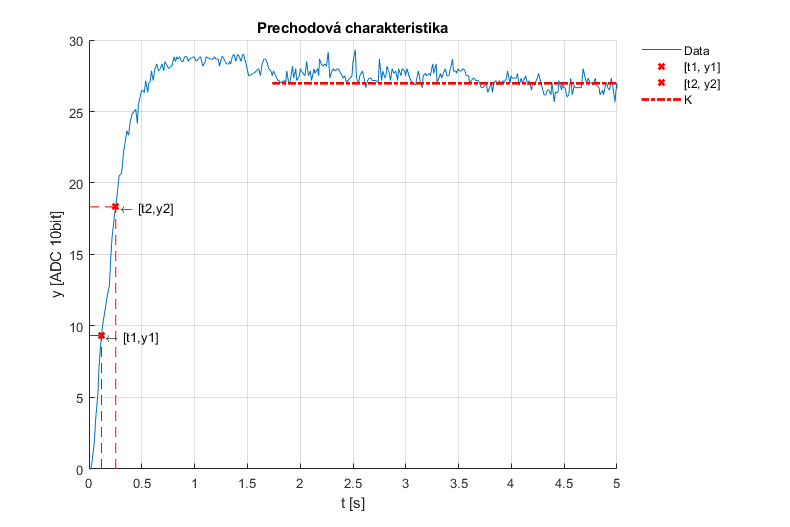

f1=figure('Position', [100 100 900 600]);
hold on;
plot(t,y);
% plot(st_t,st_y,'DisplayName','g(s)_{ident.}');
plot(t1,y1,'xr','LineWidth',2);
plot(t2,y2,'xr','LineWidth',2);
% yline(plotK,'-.r','LineWidth',2);
line([t(100),5],[plotK,plotK],'Color','red','LineStyle','-.','LineWidth',2)
line([0,t1],[y1,y1],'Color','red','LineStyle','--','LineWidth',0.5)
line([0,t2],[y2,y2],'Color','red','LineStyle','--','LineWidth',0.5)
line([t1,t1],[0,y1],'Color','red','LineStyle','--','LineWidth',0.5)
line([t2,t2],[0,y2],'Color','red','LineStyle','--','LineWidth',0.5)
legend("Location",'bestoutside');
legend('boxoff')
legend('Data','[t1, y1]','[t2, y2]','K')
txt1 = ' \leftarrow [t1,y1]';
text(t1,y1,txt1)
txt2 = ' \leftarrow [t2,y2]';
text(t2,y2,txt2)
hold off;
grid on;
xlabel('t [s]');
ylabel('y [ADC 10bit]');
xlim([0 5])
title('Prechodová charakteristika');
saveas(f1, 'figures/f_15_ident_prechod_metod.eps', 'epsc')

Prechodové charakteristiky

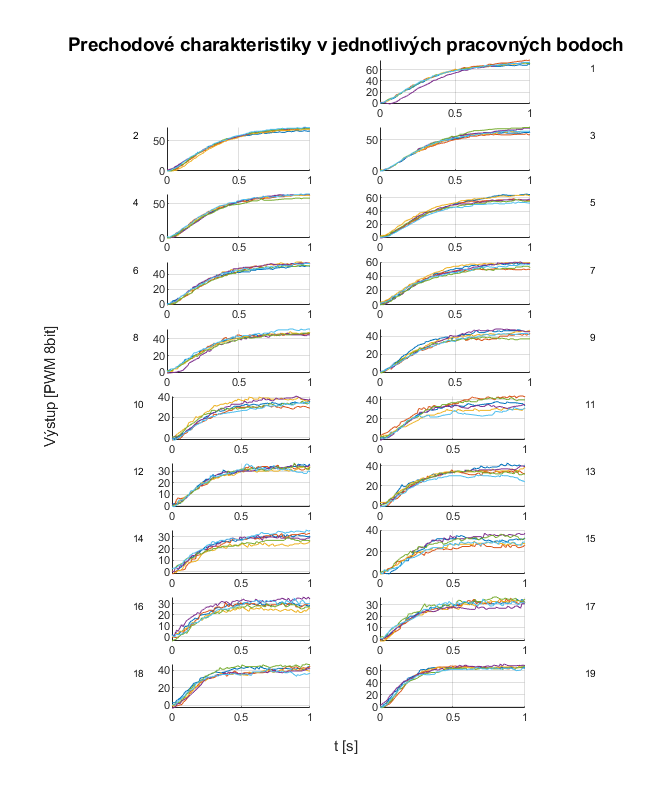

w = 750;
pomData = zeros(19,6);

for i = 1:19
   for k = 1:n
       pomData(i,k) = find((dataPlotTime(:,k)>11.95+(12*(i-1)) & dataPlotTime(:,k)<12.05+(12*(i-1))),1);
   end
end

f2 = figure('Position', [628,42,667,1000]);
for j = 2:length(id)
    subplot(length(id)/2,2,j);
    hold on
    for k=1:n
        plot(dataPlotTime((id(j-1)):id(j),k)-12*(j-1), dataPlot((id(j-1)):id(j),k)-(dataPlot(pomData(j-1,k),k))); 
    end

    grid on
    xlim([0 1])
    txt = ['u_',num2str(j)];
    dummyh = line(nan, nan, 'Linestyle', 'none', 'Marker', 'none', 'Color', 'none');
    legend('boxoff')
    legend(dummyh,num2str(j-1));
    if mod(j,2) == 1 
        legend("Location",'northwestoutside');
    else
        legend("Location",'northeastoutside');
    end
    han=axes(f2,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    ylabel(han,'Výstup [PWM 8bit]');
    xlabel(han,'t [s]');
    title(han,'Prechodové charakteristiky v jednotlivých pracovných bodoch', 'FontSize', 14);
    hold off
    
end
saveas(f2, 'figures/f_16_ident_prechodove_char.eps', 'epsc')

Prechodové charakteristiky + simulink

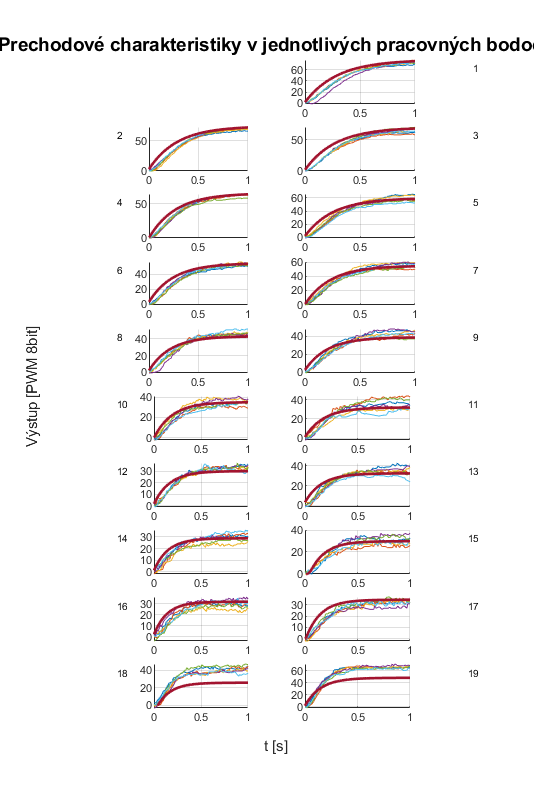

f3 = figure('Position', [628,42,667,1000]);
simY = out.y.Data;
simT = out.tout;
idsMan = [1207 2407 3608 4809 6007 7207 8408 9607 10807 12009 13211 14410 15609 16810 18013 19210 20412 21616 22810 24013]';
for j = 2:length(id)
    subplot(length(id)/2,2,j);
    hold on
    for k=1:n
        plot(dataPlotTime((id(j-1)):id(j),k)-12*(j-1), dataPlot((id(j-1)):id(j),k)-(dataPlot(pomData(j-1,k),k))); 
    end
    plot(simT((idsMan(j-1)):idsMan(j))-12*(j-1), simY((idsMan(j-1)):idsMan(j))-simY(idsMan(j-1),:), 'LineWidth',2); 
    grid on
    xlim([0 1])
    txt = ['u_',num2str(j)];
    dummyh = line(nan, nan, 'Linestyle', 'none', 'Marker', 'none', 'Color', 'none');
    legend('boxoff')
    legend(dummyh,num2str(j-1));
    if mod(j,2) == 1 
        legend("Location",'northwestoutside');
    else
        legend("Location",'northeastoutside');
    end
    han=axes(f3,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    ylabel(han,'Výstup [PWM 8bit]');
    xlabel(han,'t [s]');
    title(han,'Prechodové charakteristiky v jednotlivých pracovných bodoch', 'FontSize', 14);
    hold off
    
end
saveas(f3, 'figures/f_17_ident_prechodove_char_sim.eps', 'epsc')

Vystupný signal + Simulácia

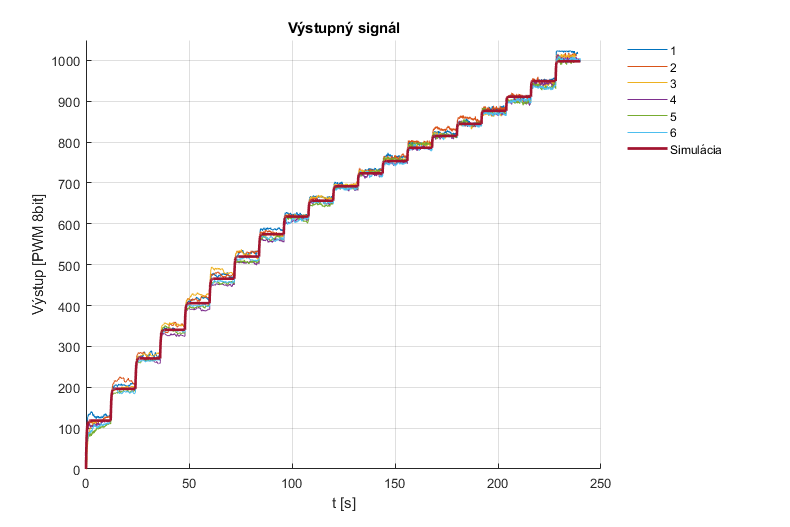

f4 = figure('Position', [100 100 900 600]);
hold on
for k=1:n
    plot(dataPlotTime(:,k), dataPlot(:,k)); 
end
plot(simT,simY,'LineWidth',2)
ylabel('Výstup [PWM 8bit]');
xlabel('t [s]');
ylim([0,1050]);
title('Výstupný signál');
legend("Location",'bestoutside');
legend('boxoff')
legend('1','2','3','4','5','6','Simulácia')
grid on
saveas(f4, 'figures/f_18_ident_prechod_char_sim.eps', 'epsc')